# Tutorial 5: Group analysis of source-space MEG during task

In this tutorial, we will demonstrate group analysis in +microstate toolbox studying whether microstate probabilities change in response to a stimulus. The analysis pipeline is based upon that presented in [1] for auditory stimuli. The full dataset presented in [1] contains 4 runs recorded over 2 separate sessions for 30 participants. 

In [1], microstate probabilities during the pre-stimulus and post-auditory-stimulus periods were compared. Here, we will expand upon this and compare microstate probabilities between standard and deviant auditory stimuli. 

This example will reproduce the analysis described in section 3.4 of the toolbox manuscript [2]. 

References: 

[1] Tait and Zhang (2021) bioRxiv 2021.03.25.436979; doi: [https://doi.org/10.1101/2021.03.25.436979](https://doi.org/10.1101/2021.03.25.436979) 

[2] Tait and Zhang (2021) bioRxiv 2021.07.13.452193; doi: [https://doi.org/10.1101/2021.07.13.452193](https://doi.org/10.1101/2021.07.13.452193) 

### Download the data and add to the path

The first thing we need to do is make sure the data is downloaded and that MATLAB can "see" the data. We have included a script to do this. The line of code below runs this script. If this is your first time running the tutorial, you will get a pop-up asking whether you wish to download the tutorial data. You must download this to proceed. 

check_for_data

If you got an error in this section, you might not have the folder toolbox-master on your Matlab path. Make sure to add this folder to your path, and re-run this section.

### Load and visualise the data

The first step of the pipeline in [1] was to perform microstate analysis on the continuous source-reconstructed MEG recording. The full MEG data is available from the Open Science Framework (https://osf.io/db9u4/ in the folder MEG-Auditory), but this does not need to be downloaded for the purposes of this tutorial. We processed the MEG data identically to how was described in tutorial 2, resulting in a *cohort* object containing the microstate sequences for each MEG scan. This *cohort* object is stored in the file `tutorial5_data.mat`, which we will load in now. 

% Import continuous data
load('tutorial5_data.mat')

% List variables in workspace
who


Your variables are:

GroupMaps             d                     info_TANOVA           p_TANOVA              
ans                   dataFC_LP             layout                p_coverage            
coh                   dataFIC_LP            mapSimilarity         toolbox_path          
coh_grandavg          datadir               ms                    trlinfo               
cohort_sim            i                     orderedMaps           
cohort_task           ind_plot_alignedmaps  p                     



As can be seen in the console output, there are two variables in `tutorial5_data.mat`, named `cohort_task` and `trlinfo`. The variable `cohort_task` is a +microstate *cohort* object containing the continuous datasets, which have been given microstate sequences aligned to the template maps from [1]. We can view the microstate sequences and template maps using the code below:

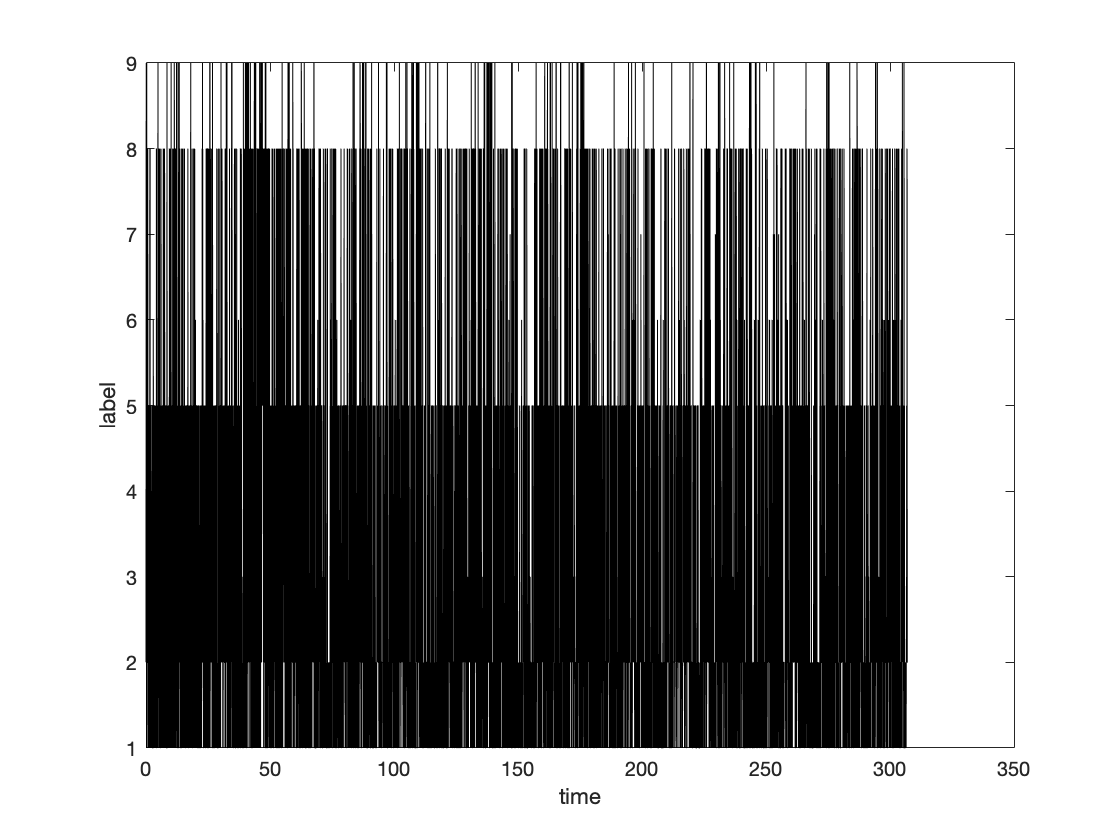

% View microstate sequence for individual 1
cohort_task.individual(1).plot('label')

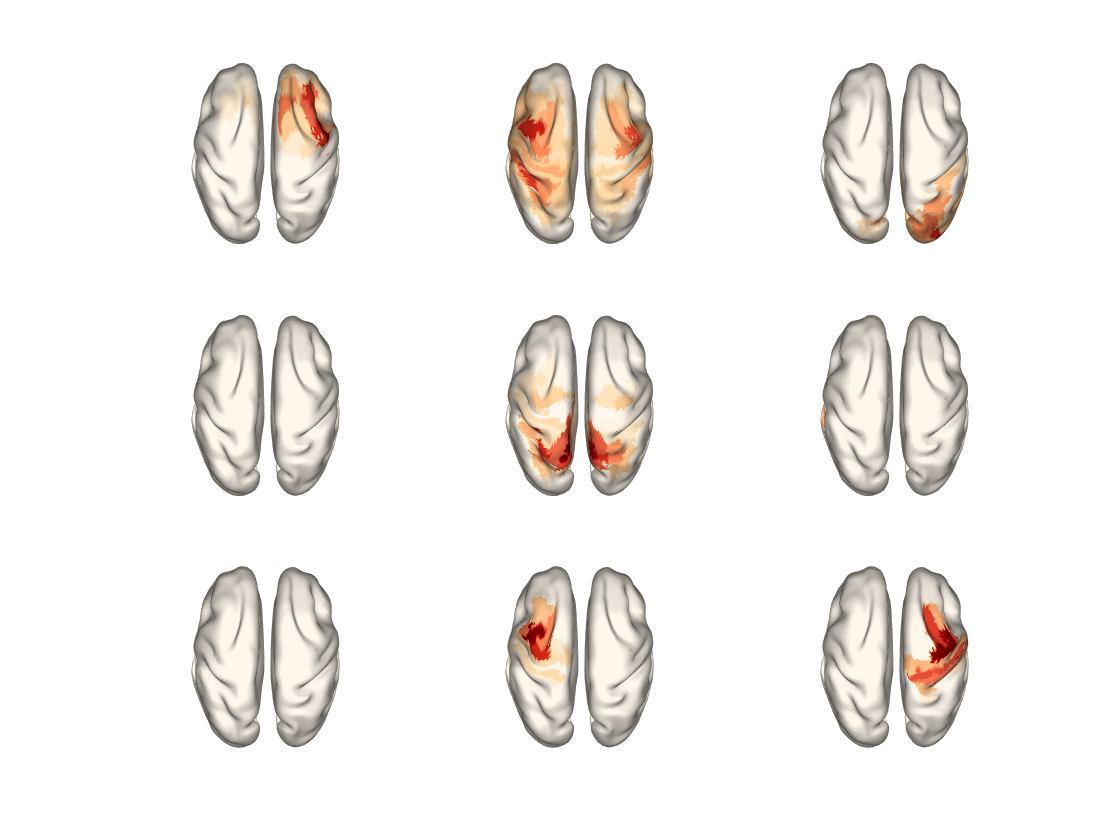

% For more details on the plotting code below, see tutorial 2. 
layout = load('layout') ; 
cohort_task.plot('globalmaps',layout,'cscale',[0.5,1])

By clicking the "Open in figure window" button in the top right of the figure, you can interactively rotate these plots to view the full surface. 

The 2nd variable is `trlinfo`. This is a 1x120 cell, where cell element `trlinfo{i}` is the information on stimuli for participant `i`. Each element in the cell is a Number of trials x 2 array, where the first column contains times of the stimuli and the second column contains an ID (i.e. a number) corresponding to the type of stimulus. In our dataset, ID=1 are standard stimuli and ID=2 to 9 are different types of deviants. 

### Convert to trials

The first step to testing microstate responses to stimuli is to segment the continuous data into trials, all sampled identically from 100ms prior to the stimulus to 350ms post-stimulus. We will keep the sampling rate at 256 Hz, which is the sampling rate of the data. To do this, we use the function `define_trials`. 

% Make a regular time vector on which to sample
time = [flipud((0:(-1/256):-0.1)')' , (1/256):(1/256):0.350] ; % -0.1:(1/256):0.35 centred around 0

% Initialize a cohort object which concatenates trials from all
% participants
cohort_trl = microstate.cohort ; 

% Loop over participants, segment continuous data into trials, and add trials to cohort_trl
num_scans = length(cohort_task.individual) ; 
conditions = {'Standard','Duration Deviant','Gap Deviant','Direction Deviant L','Direction Deviant R','Intensity Deviant High','Intensity Deviant Low','Frequency Deviant High','Frequency Deviant Low'} ; 
for i = 1:num_scans
    fprintf('Converting scan %d of %d from continuous to trials\n',i,num_scans)
    % one session has missing trial information so skip this
    if isempty(trlinfo{i}) ; continue ; end
    
    % segment continuous data
    stimulus_times = trlinfo{i}(:,1) ; 
    stimulus_ids = trlinfo{i}(:,2) ; 
    trl = cohort_task.individual(i).define_trials(time,stimulus_times,stimulus_ids) ; 
    
    % add to cohort_trl
    cohort_trl = cohort_trl.add_individuals(trl.individual,conditions(trl.condition)) ; 
end

Converting scan 1 of 120 from continuous to trials
Converting scan 2 of 120 from continuous to trials
Converting scan 3 of 120 from continuous to trials
Converting scan 4 of 120 from continuous to trials
Converting scan 5 of 120 from continuous to trials
Converting scan 6 of 120 from continuous to trials
Converting scan 7 of 120 from continuous to trials
Converting scan 8 of 120 from continuous to trials
Converting scan 9 of 120 from continuous to trials
Converting scan 10 of 120 from continuous to trials
Converting scan 11 of 120 from continuous to trials
Converting scan 12 of 120 from continuous to trials
Converting scan 13 of 120 from continuous to trials
Converting scan 14 of 120 from continuous to trials
Converting scan 15 of 120 from continuous to trials
Converting scan 16 of 120 from continuous to trials
Converting scan 17 of 120 from continuous to trials
Converting scan 18 of 120 from continuous to trials
Converting scan 19 of 120 from continuous to trials
Converting scan 20 of

We now have a *cohort* object `cohort_trl` which is a concatenation of all trials across all participants. Each trial has the same time axis, relative to the stimulus time. `cohort_trl.condition` contains the numeric ID of the trial, while `cohort_trl.conditionlabels` contains information on the type of trial corresponding to each numeric ID. 

### Calculate chi2 distance between pre-stimulus and post-stimulus probabilities

In [1], we presented a pipeline to compare pre-stimulus and post-stimulus microstate probabilities across all stimuli. In the code below, we can reproduce this analysis. 

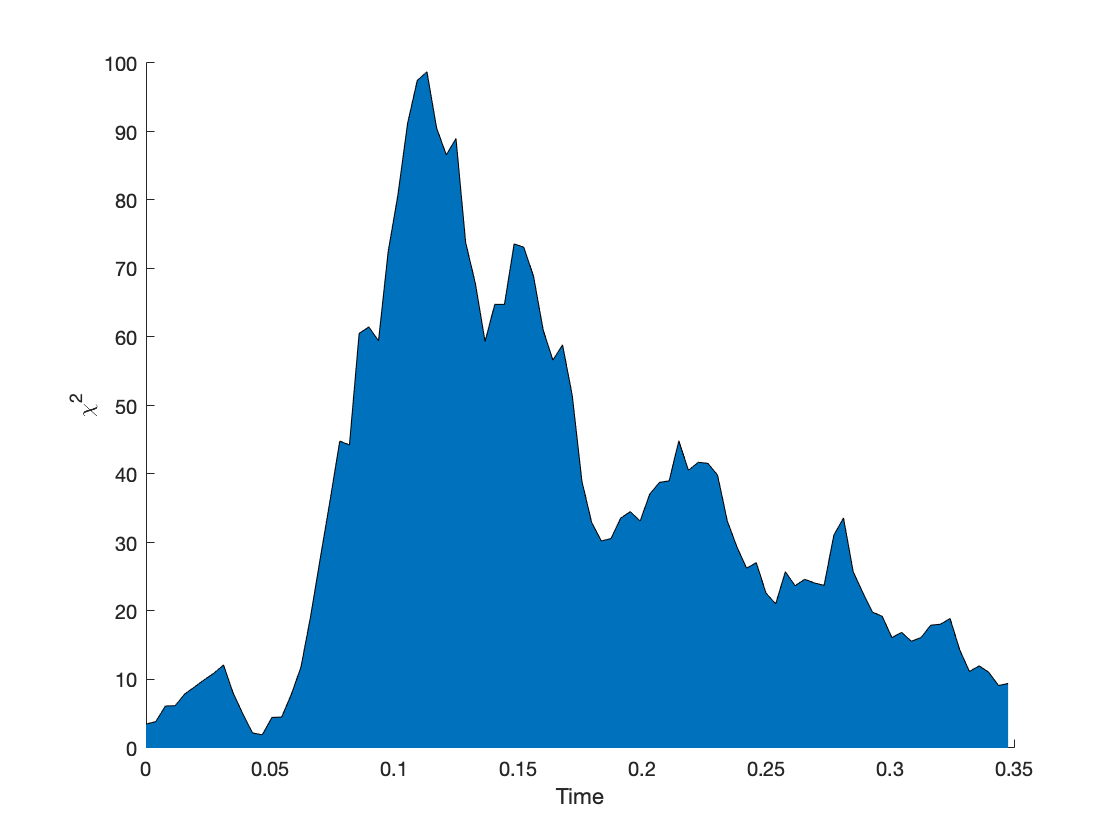

% Calculate chi2 distance
info_all = cohort_trl.erp_chi2stateprobs('prestim',conditions) ; 

% Plot chi2 distance
figure
microstate.functions.erp_chi2_plot(info_all) ; 

There is a clear peak in chi2 at approximately 100ms post-stimulus, in line with the results from [1]. We can additionally specify single or groups of stimuli. For example, if we want to look at the 8 deviant stimuli: 

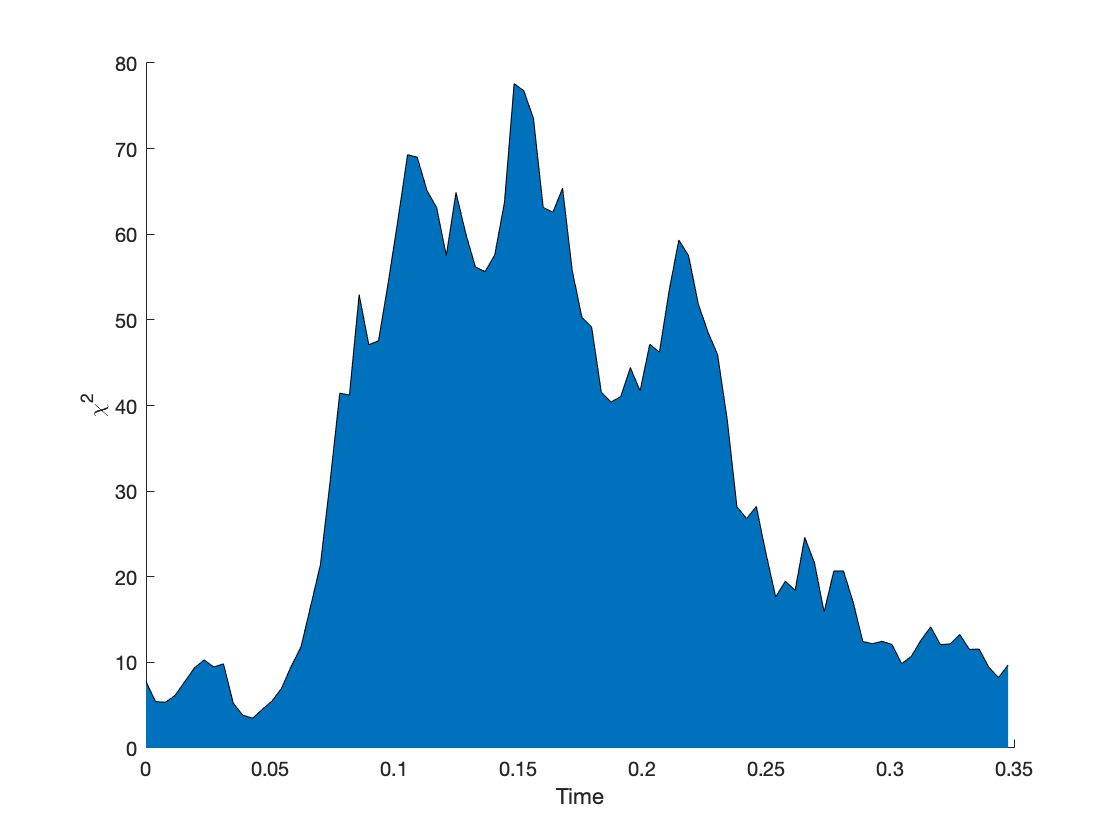

% Calculate chi2 distance
info_dev = cohort_trl.erp_chi2stateprobs('prestim',conditions(2:9)) ; 

% Plot chi2 distance
figure
microstate.functions.erp_chi2_plot(info_dev) ; 

### Compare standard vs deviants

We are also able to compare microstate probabilities for standards vs deviants, as opposed to post-stimulus vs pre-stimulus. The code below shows how to do this. We use `conditions(1)` for our expected count (i.e. the baseline statistic), as this contains the standard stimuli. We use conditions(2:end) for our observed count, as this contains all deviants. 

% Calculate chi2 distance
rng('default') % for reproducibility
info_stdvsdev = cohort_trl.erp_chi2stateprobs(conditions(1),conditions(2:end)) 

Cluster permutation testing (chi2), permutation 2000 of 2000

info_stdvsdev = struct with fields:
                 time: [1×115 double]
     pearsonResiduals: [9×115 double]
                 chi2: [1×115 double]
            threshold: 15.5073
    uncorrected_pvals: [1×115 double]
      maxcluster_time: [0.1289 0.2500]
      maxcluster_pval: 0.0310


Let us test for significance. You'll notice in the output above there are two fields named `maxcluster_time` and `maxcluster_pval`. These values contain the times and p-values for the maximal cluster using cluster permutation testing. Since the cluster permutation test requires permuting the labels of the conditions, these values were not present for the pre-stimulus vs post-stimulus comparisons in the previous section. Here, we got p=0.0310 from cluster permutation testing, suggesting a significant difference in microstate probabilities. This cluster had a time period 129-250 ms, in line with mismatch negativity literature. The code below plots these results.

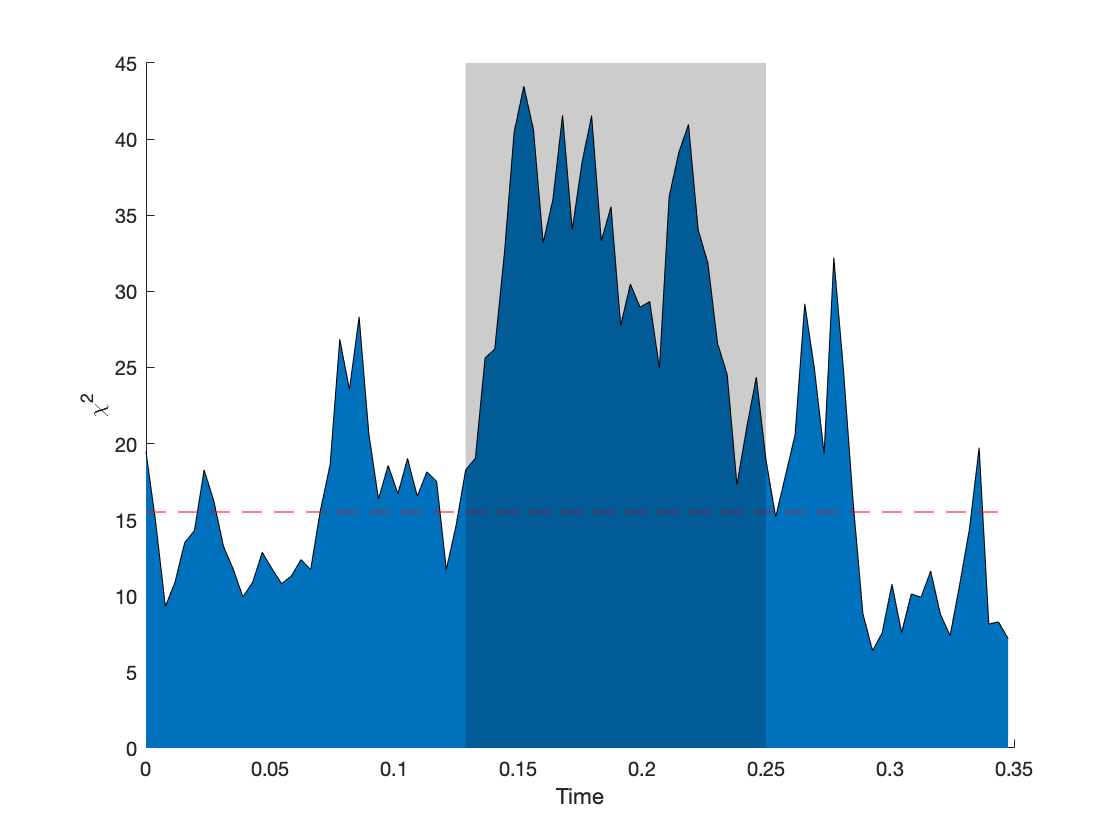

% Plot chi2 distance and significant values
figure
microstate.functions.erp_chi2_plot(info_stdvsdev,'clusterperm') ; 

To explore which states differ probability during in this period, we will plot the Pearson residuals at the sample with maximum chi2 value. As a rough rule of thumb, a Pearson residual of >3 indicates a strong effect size. 

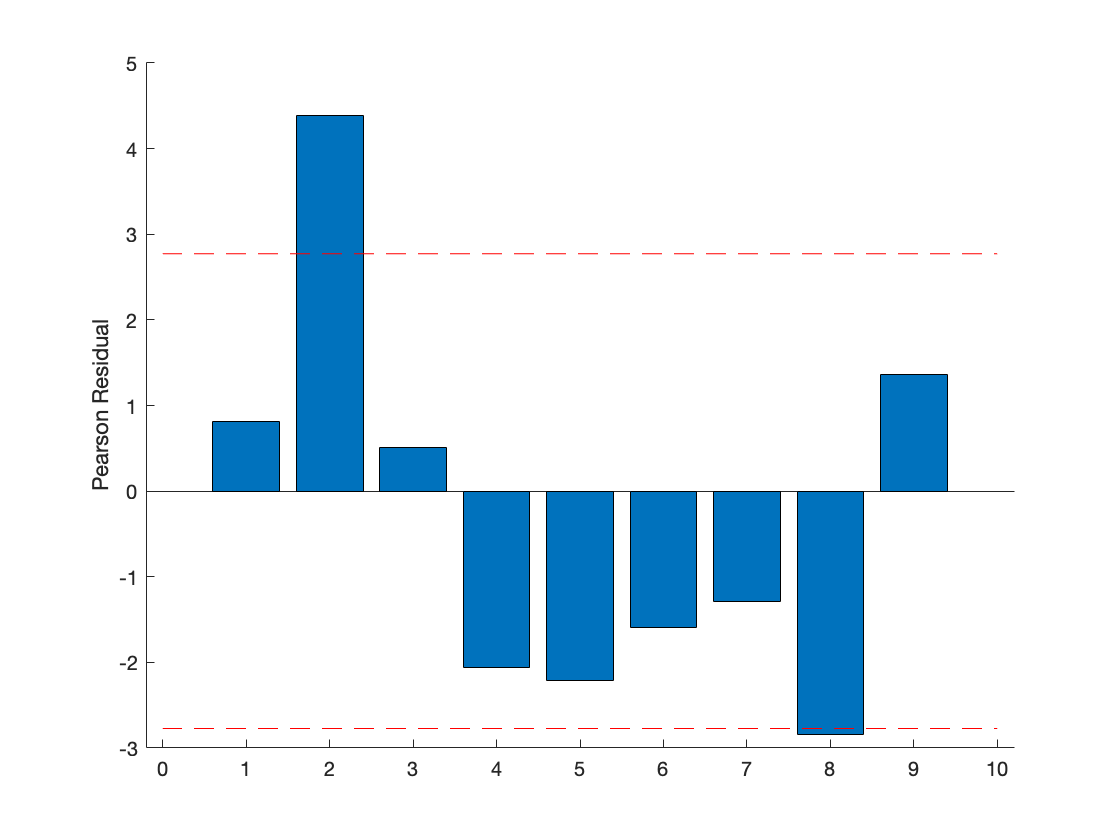

% Plot
figure
microstate.functions.erp_chi2_plot(info_stdvsdev,'residual')

This plot suggests that microstate 2 (which contains frontal, and temporal including auditory cortex) is more likely in the deviants than standards. 